clc; clear variables;

### QR Decompositions

Reconstruction and Orthogonality erros on random matrices in increasing size. 

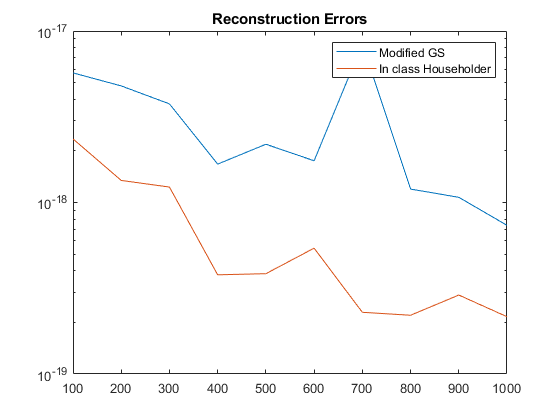

MatrixSizes = 100: 100: 1000;
ReconstructionErrors = zeros(2, length(MatrixSizes)); 
OrthogonalityErrors = zeros(2, length(MatrixSizes));
for I = 1: length(MatrixSizes)
    RandMatrix = rand(MatrixSizes(I));
    [E1, E2] = QRErrorGet(RandMatrix, @ModifiedGS);
    ReconstructionErrors(1, I) = E1; 
    OrthogonalityErrors(1, I) = E2; 
    [E1, E2] = QRErrorGet(RandMatrix, @qr);
    ReconstructionErrors(2, I) = E1; 
    OrthogonalityErrors(2, I) = E2;
end
close all
figure;
semilogy(MatrixSizes, ReconstructionErrors(1, :)); hold on;
semilogy(MatrixSizes, ReconstructionErrors(2, :))
legend("Modified GS", "In class Householder");
title("Reconstruction Errors");
saveas(gcf, "ReconstructionError", "png");

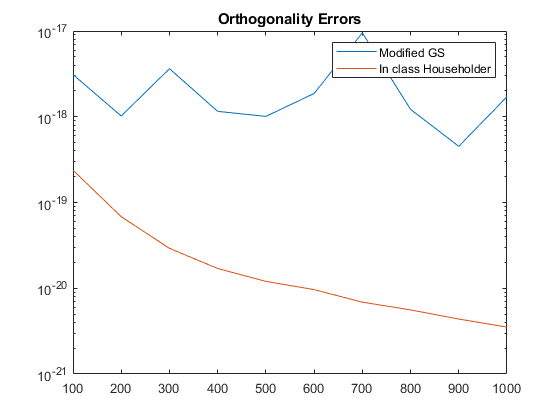

figure;

semilogy(MatrixSizes, OrthogonalityErrors(1, :)); hold on;
semilogy(MatrixSizes, OrthogonalityErrors(2, :));
legend("Modified GS", "In class Householder");
title("Orthogonality Errors");
saveas(gcf, "OrthogonalityErrors", "png");

Reconstruction Error and Orthogonality Errors on badly conditioned matrices. 

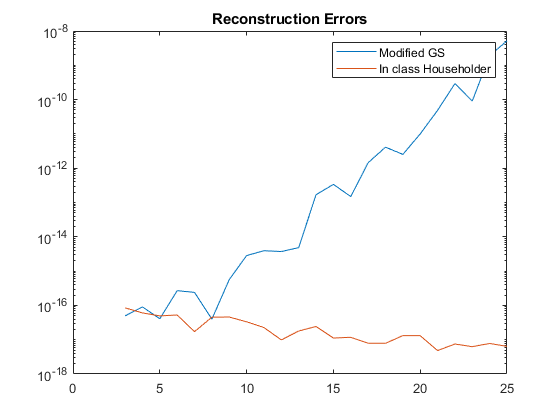

MatrixSizes = 3: 1: 25;
ReconstructionErrors = zeros(2, length(MatrixSizes)); 
OrthogonalityErrors = zeros(2, length(MatrixSizes));
for I = 1: length(MatrixSizes)
    N = MatrixSizes(I);
    RandMatrix = vander(linspace(-1, 1, N));
    [E1, E2] = QRErrorGet(RandMatrix, @ModifiedGS);
    ReconstructionErrors(1, I) = E1; 
    OrthogonalityErrors(1, I) = E2; 
    [E1, E2] = QRErrorGet(RandMatrix, @qr);
    ReconstructionErrors(2, I) = E1; 
    OrthogonalityErrors(2, I) = E2;
end
close all
figure;
semilogy(MatrixSizes, ReconstructionErrors(1, :)); hold on;
semilogy(MatrixSizes, ReconstructionErrors(2, :))
legend("Modified GS", "In class Householder");
title("Reconstruction Errors");
saveas(gcf, "ReconstructionError", "png");

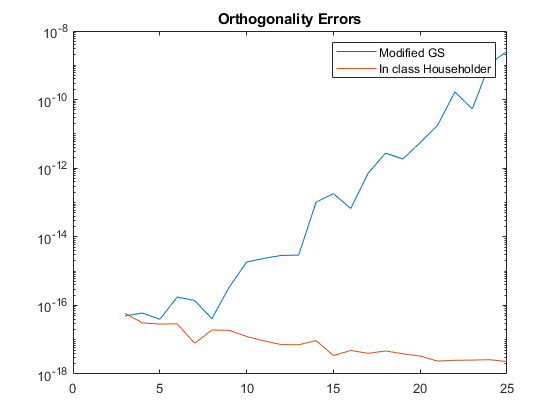


figure;
semilogy(MatrixSizes, OrthogonalityErrors(1, :)); hold on;
semilogy(MatrixSizes, OrthogonalityErrors(2, :));
legend("Modified GS", "In class Householder");
title("Orthogonality Errors");
saveas(gcf, "OrthogonalityErrors", "png");

Another bad matrix, this time it's the hilbert matrix.

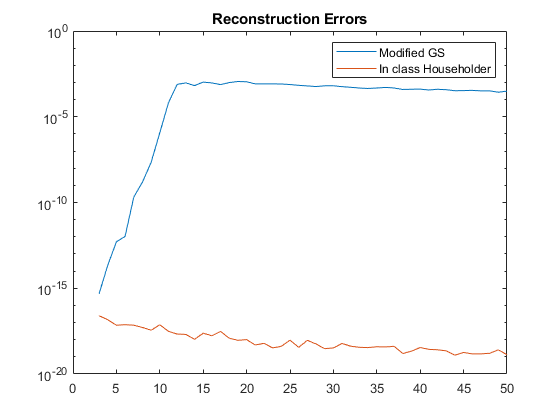


MatrixSizes = 3: 1: 50;
ReconstructionErrors = zeros(2, length(MatrixSizes)); 
OrthogonalityErrors = zeros(2, length(MatrixSizes));
for I = 1: length(MatrixSizes)
    N = MatrixSizes(I);
    [X, Y] = meshgrid(1:N);
    RandMatrix = 1./(X + Y);
    [E1, E2] = QRErrorGet(RandMatrix, @ModifiedGS);
    ReconstructionErrors(1, I) = E1; 
    OrthogonalityErrors(1, I) = E2; 
    [E1, E2] = QRErrorGet(RandMatrix, @qr);
    ReconstructionErrors(2, I) = E1; 
    OrthogonalityErrors(2, I) = E2;
end

close all
figure;
semilogy(MatrixSizes, ReconstructionErrors(1, :)); hold on;
semilogy(MatrixSizes, ReconstructionErrors(2, :))
legend("Modified GS", "In class Householder");
title("Reconstruction Errors");
saveas(gcf, "ReconstructionError", "png");

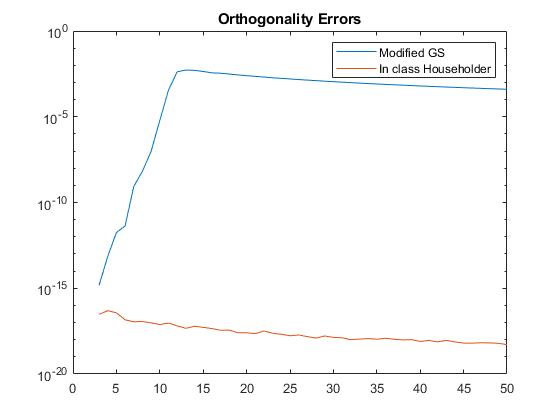


figure;
semilogy(MatrixSizes, OrthogonalityErrors(1, :)); hold on;
semilogy(MatrixSizes, OrthogonalityErrors(2, :));
legend("Modified GS", "In class Householder");
title("Orthogonality Errors");
saveas(gcf, "OrthogonalityErrors", "png");

### Polynomials Conditioning

II (a), Plotting the badly conditioned polynomials: 

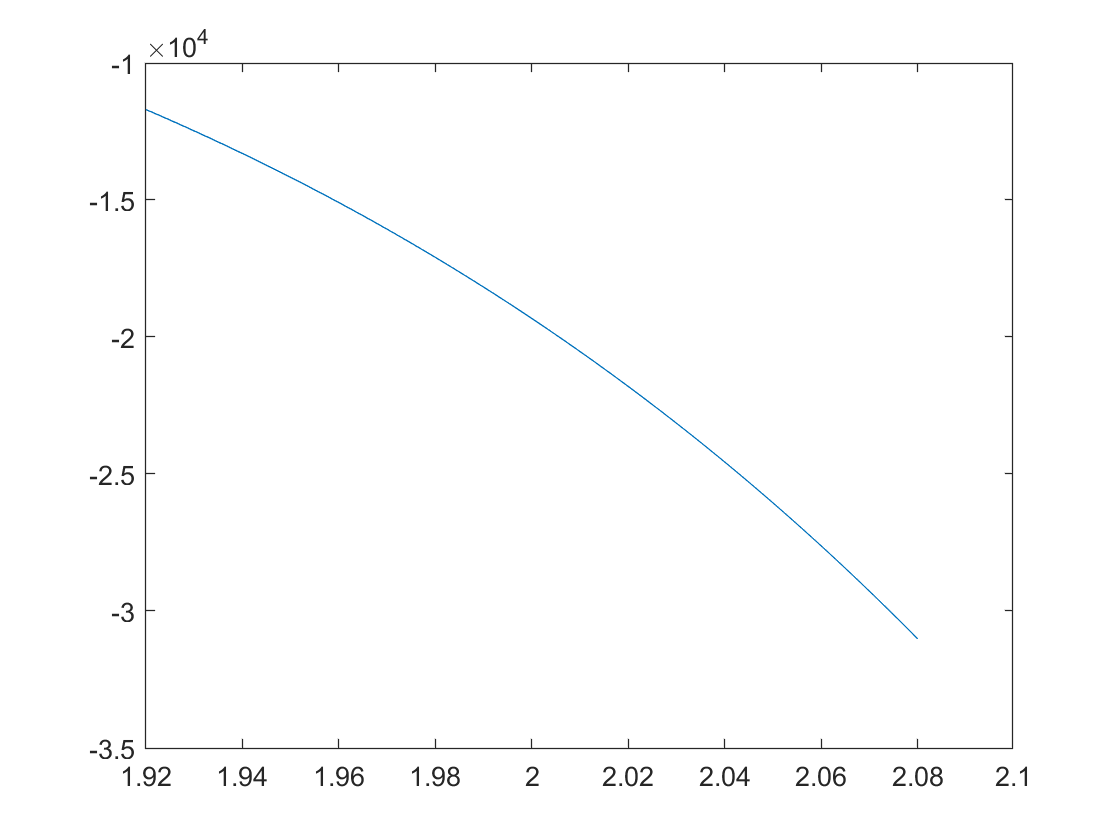

Xs = 1.920: 0.001: 2.08; 
plot(Xs, BadPolynomial(Xs))
saveas(gcf, "BadPolynomial.png", "png")

II (b), Plotting the goodly conditioned polynomials: 

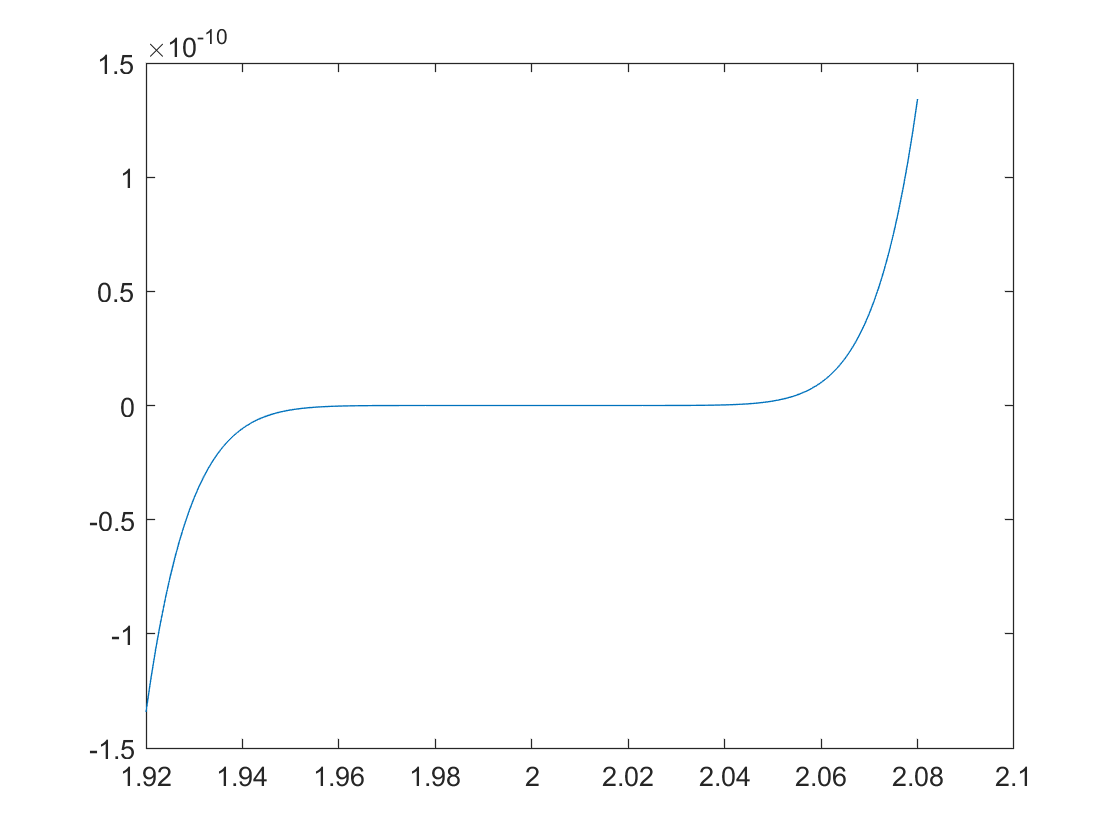

Xs = 1.920: 0.001: 2.08; 
plot(Xs, GoodPolynomial(Xs))

saveas(gcf, "GoodPolynomial.png", "png")

### Matrix Conditioning